phi=38.1167; % geografische Breite Palermo
t=0:1:24;
H= 15*(t-12); %Stundenwinkel
datum = datetime('2024-10-17');
doy = day(datum,'dayofyear');
delta=23.45*sin((2*pi/365)*(doy+284));

sonnenaufgang = fzero(@(t) (sind(phi)*sind(delta)+cosd(phi)*cosd(delta)*cosd(15*(t-12))),[0 12]);
sonnenuntergang = fzero(@(t) (sind(phi)*sind(delta)+cosd(phi)*cosd(delta)*cosd(15*(t-12))),[12 24]);

fprintf('Sonnenaufgang am Abgabetermin: %d:%.0f Uhr\n', fix(sonnenaufgang) ,mod(sonnenaufgang,1)*60);

Sonnenaufgang am Abgabetermin: 6:34 Uhr


fprintf('Sonnenuntergang am Abgabetermin: %d:%.0f Uhr\n', fix(sonnenuntergang) ,mod(sonnenuntergang,1)*60);

Sonnenuntergang am Abgabetermin: 17:26 Uhr


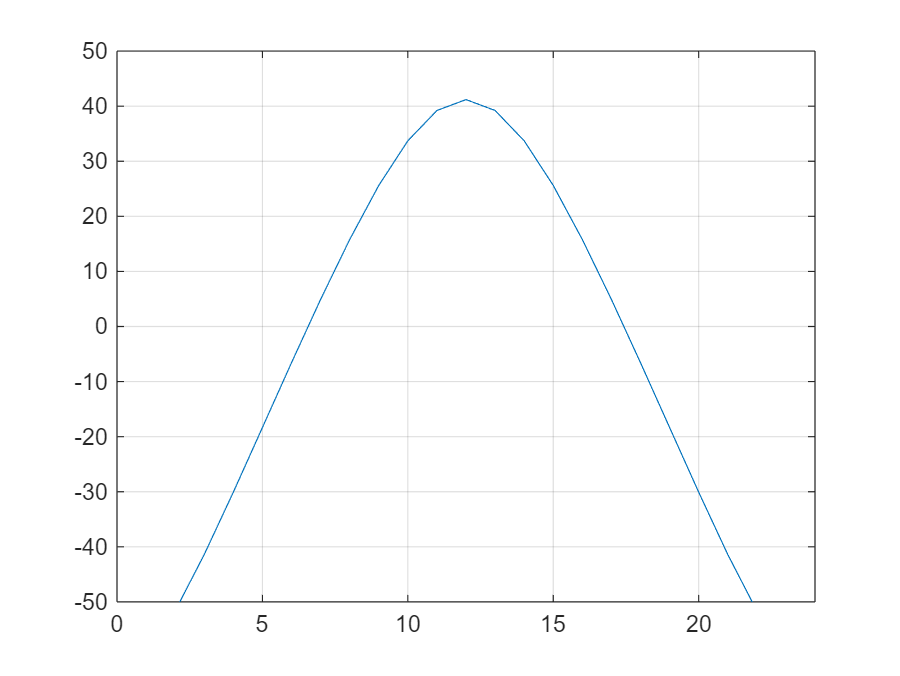


sin_a=@(t) (sind(phi)*sind(delta)+cosd(phi)*cosd(delta)*cosd(15*(t-12)));
a = asind(sin_a(t));
plot(t,a)
ylim([-50 50]);
xlim([0 24]);
grid on;


max=fminbnd(@(t) (-1*(sind(phi)*sind(delta)+cosd(phi)*cosd(delta)*cosd(15*(t-12)))),0,24);
max_deg= asind(sin_a(max));
fprintf('Maximale Sonnenhöhe von %f° um %.2f Uhr \n', max_deg ,max);

Maximale Sonnenhöhe von 41.192288° um 12.00 Uhr 
